# **Problem E9.8**


$$F\left(x\right)=\frac{1}{2}x^T \left\lbrack \begin{array}{cc}
7 & -9\\
-9 & -17
\end{array}\right\rbrack x+\left\lbrack \begin{array}{cc}
16 & 8
\end{array}\right\rbrack x$$


## i. Sketching the contour plot

We perform the calculations by hand and have MATLAB draw up the contour plot for us so that it looks nicer is better prepared for the following parts.


$$\nabla F\left(x\right)=A\;x+d=\left\lbrack \begin{array}{cc}
7 & -9\\
-9 & -17
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
16\\
8
\end{array}\right\rbrack \;$$


We will set this to 0 to find the stationary points of $F\left(x\right)$:


$$\left\lbrack \begin{array}{cc}
7 & -9\\
-9 & -17
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
16\\
8
\end{array}\right\rbrack =0\to x={\left\lbrack \begin{array}{cc}
7 & -9\\
-9 & -17
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
-16\\
-8
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-1\\
1
\end{array}\right\rbrack$$


Now in order to find out which type of stationary point this is, we will analyze the Hessian:

$\nabla^2 F\left(x\right)=A=\left\lbrack \begin{array}{cc}
7 & -9\\
-9 & -17
\end{array}\right\rbrack$and $\textrm{eig}\left(\nabla^2 F\left(x\right)\right):\lambda_1 =-20,\;\;\lambda_2 =10\to \textrm{hessian}\;\textrm{is}\;\textrm{indefinite}\to \textrm{saddle}\;\textrm{point}$

Therefore we have an elongated saddle point at $\left\lbrack \begin{array}{c}
-1\\
1
\end{array}\right\rbrack$.

Now we will see the contour plot to confirm our suspicion:

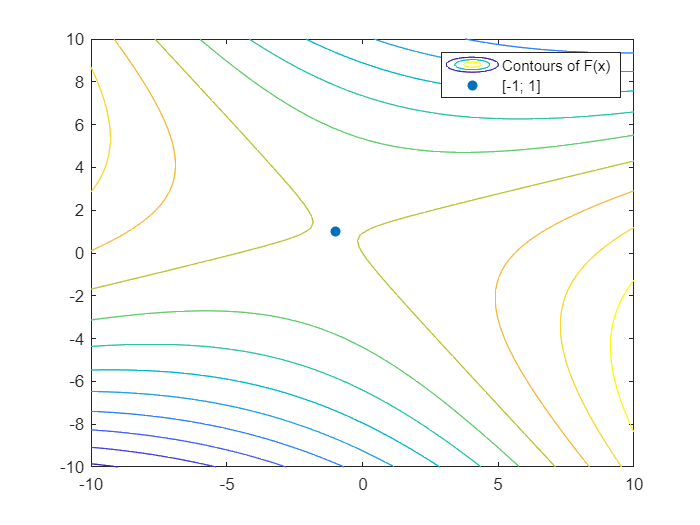

syms x1 x2 real
X = [x1; x2];
fx = (1/2)*X'*[7 -9; -9 -17]*X + [16 8]*X;
fcontour(fx, [-10 10 -10 10]);
hold on;
scatter(-1, 1, 'filled');
legend('Contours of F(x)', '[-1; 1]')
hold off;

## ii. One iteration of Newton's method

According to Newton's method:


$$x_{k+1} =x_k -A_k^{-1} g_k$$


We know that $A_k =A$in a quadratic function and therefore $A_k^{-1} =A^{-1} =\left\lbrack \begin{array}{cc}
0\ldotp 085 & -0\ldotp 045\\
-0\ldotp 045 & -0\ldotp 035
\end{array}\right\rbrack$and $x_0 =\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack$.

Additionally we know that $g_k =\nabla {F\left(x\right)}_{x\;={\;x}_k } =\left\lbrack \begin{array}{cc}
7 & -9\\
-9 & -17
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
16\\
8
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
12\\
-44
\end{array}\right\rbrack$. Finally we can perform the first step:


$$x_1 =\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
0\ldotp 085 & -0\ldotp 045\\
-0\ldotp 045 & -0\ldotp 035
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
12\\
-44
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-1\\
1
\end{array}\right\rbrack$$


As we can see, Newton's method converges to the stationary point in one iteration.

## iii. 

No. As we have proven in the first part. The only stationary point of this quadratic function is a saddle point. While we did manage to get to the saddle point from the initial guess with only on iteration of Newton's method, we have not reached a "minimum".

## iv.

We will perform steepest descent with $\alpha =0\ldotp 02$and plot the result upon the original contour plot.

Steepest Descent:


$$x_{k+1} =x_k -\alpha \;g_k$$


Note: in order to trace the path, we will keep a history of $x_k$s and then connect them sequentially with arrows starting from $x_{k-1}$and ending at $x_k$.

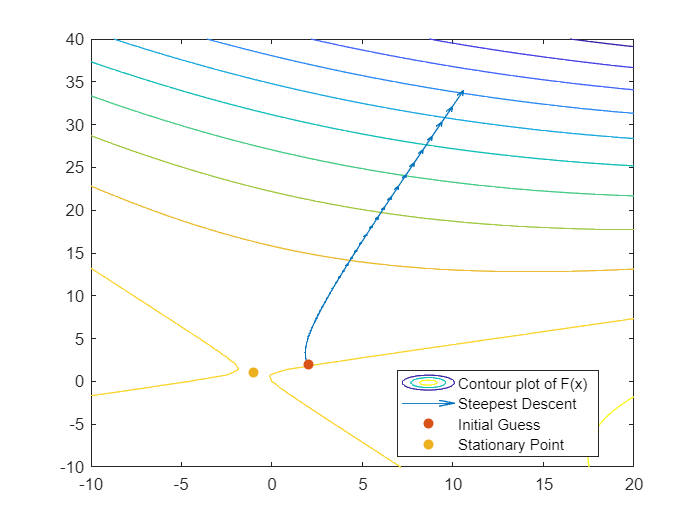

num_iters = 50;
hist_X = zeros([2, num_iters + 1]);
g = gradient(fx, X);
hist_X(:, 1) = [2; 2];
alpha = 0.003;
for i=2:num_iters+1
    hist_X(:, i) = hist_X(:, i-1) - alpha*subs(g, X, hist_X(:, i-1)); 
end
fcontour(fx, [-10 20 -10 40]);
hold on;
u = diff(hist_X(1,:));
v = diff(hist_X(2,:));
quiver(hist_X(1,1:end-1), hist_X(2,1:end-1), u, v, 0);
hold on;
scatter(2, 2, 'filled');
hold on;
scatter(-1, 1, 'filled');
legend('Contour plot of F(x)', 'Steepest Descent', 'Initial Guess', 'Stationary Point', 'Location','best')
hold off;

As we can see, not only does Steepest Descent not converge towards the Saddle Point obtained from part (ii), it diverges from it even though the initial guess reasonably close to the stationary point. The reason for this is that Steepest Descent does not actively try to converge towards an Stationary Point, but rather takes the steepest route down the surface of the function. Now if a strong minimum exists, it will have to occur at a Stationary Point and because SD always picks the steepest route down the surface it will eventually (given a small enough learning rate), converge to that point simply because the steepest path leads the algorithm to it. 

In a nutshell, SD converging to a Stationary Point is a byproduct of the fact it will take the steepest path on the surface of the function at each step. This means that given a function $F\left(x\right)$whose sole Stationary Point is a Saddle Point, SD will disregard this and keep moving in the direction of the steepest descent, away from the Saddle Point. As we move further away from the Saddle Point, the surface of the function becomes steeper and steeper, resulting in larger steps which is visible from the plot drawn above.